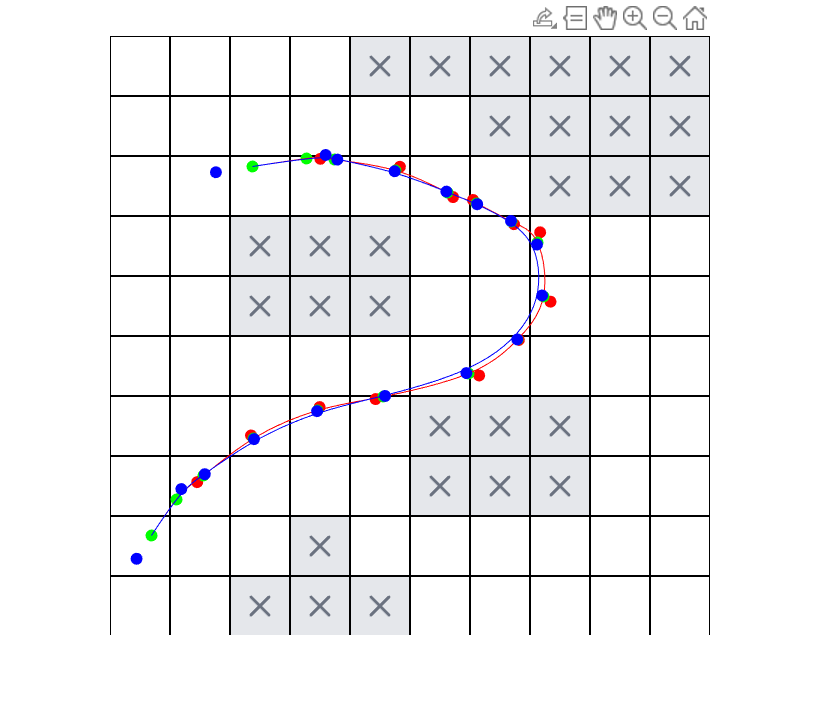

imshow("map1.png")
hold on
[xi,yi] = getpts();
Path = [xi yi];
%Path = [1 1;2 2;3.2 5; 3.5 5.5;4 6; 7 5; 7 8];
M_k = [1 / 6, 4 / 6, 1 / 6, 0;
    -3 / 6, 0, 3 / 6, 0;
    3 / 6, -6 / 6, 3 / 6, 0;
    -1 / 6, 3 / 6, -3 / 6, 1 / 6 ];
A = M_k(1,:);
for i = 2:size(Path,1)
    B = A(end,:);
    A = [A,zeros(i - 1,1)];
    A = [A;0,B];
end
A = [A;zeros(1,size(Path,1) - 1),M_k(2,:)];
A = [A;zeros(1,size(Path,1)),M_k(2,1:end-1)];
A = [A;M_k(2,:),zeros(1,size(Path,1) - 1)];
b = [Path;0,0;0 0;0 0];
BsplineControlPoint = A\b;
scatter(BsplineControlPoint(:,1),BsplineControlPoint(:,2),"filled",'r')
hold on
scatter(Path(:,1),Path(:,2),"filled",'g')


[x, y] = GetTrajectory( BsplineControlPoint,4);
plot(x,y,'r')
hold on

OptimizedControlPos = BsplineControlPoint;
for p = 4:size(BsplineControlPoint,1) - 4
    OptimizedControlPos(p,:) =OptimizedControlPos(p,:) + (BsplineControlPoint(p - 1,:) - BsplineControlPoint(p,:)) * 0.2  + (BsplineControlPoint(p + 1,:) - BsplineControlPoint(p,:)) * 0.2 ;
end

scatter(OptimizedControlPos(:,1),OptimizedControlPos(:,2),"filled",'b')
hold on
[x, y] = GetTrajectory( OptimizedControlPos,4);
plot(x,y,'b')
hold on